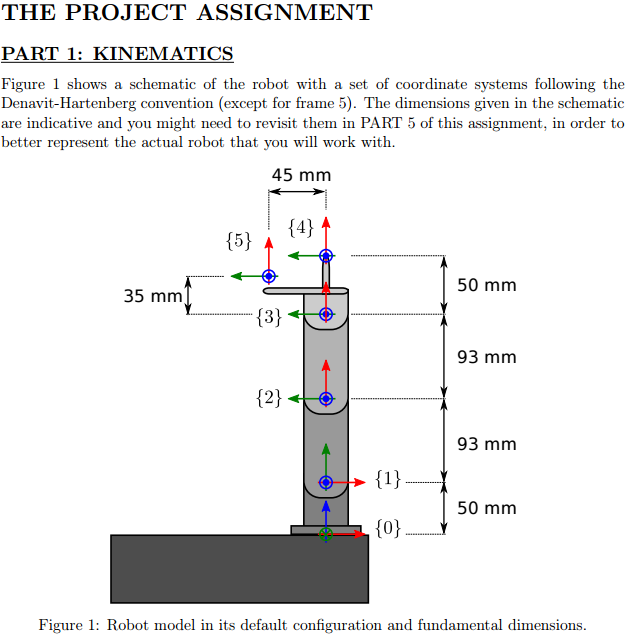

syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6
syms pi_sym
theta_1; %theta_1__star;
d_1 = 0.050;
a_1 = 0;
alpha_1 = pi_sym/2; %%

theta_2 = theta_2 + pi_sym/2; %theta_2__star;
d_2 = 0;
a_2 = 0.093;
alpha_2 = 0;

theta_3; %theta_3__star;
d_3 = 0; 
a_3 = 0.093;
alpha_3 = 0;

theta_4; %theta_4__star;
d_4 = 0;
a_4 = 0.05;
alpha_4 = 0;

%syms alpha_1 alpha_2 alpha_3 alpha_4

theta = [theta_1, theta_2, theta_3, theta_4];
d     = [d_1,     d_2,     d_3,     d_4];
a     = [a_1,     a_2,     a_3,     a_4];
alpha = [alpha_1, alpha_2, alpha_3, alpha_4];
A = sym(zeros(4,4,4)); 

for i = 1:4
    A(:,:,i) = [cos(theta(i)), -sin(theta(i))*cos(alpha(i)),  sin(theta(i))*sin(alpha(i)), a(i)*cos(theta(i));  
                sin(theta(i)),  cos(theta(i))*cos(alpha(i)), -cos(theta(i))*sin(alpha(i)), a(i)*sin(theta(i)); 
                0,              sin(alpha(i)),                cos(alpha(i)),               d(i); 
                0,              0,                            0,                           1]; 
end

A_1 = subs(A(:,:,1), alpha_1, pi/2)

$$A\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

theta_2_new = sym('theta_2');
A_2 = subs(A(:,:,2), [cos(theta_2_pi), sin(theta_2)], [-sin(theta_2_new), cos(theta_2_new)])

$$A\_2 = \left(\begin{array}{cccc} -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & -\frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \frac{93\,\cos\left(\theta_{2}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3 = vpa(A(:,:,3), 2)

$$A\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -1.0\,\sin\left(\theta_{3}\right) & 0 & 0.093\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0.093\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

A_4 = vpa(A(:,:,4), 2) 

$$A\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -1.0\,\sin\left(\theta_{4}\right) & 0 & 0.05\,\cos\left(\theta_{4}\right)\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0.05\,\sin\left(\theta_{4}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$


T_4__0 = vpa(A_1 * A_2 * A_3 * A_4, 2)


T_5__4 = [1, 0, 0, -0.015;
          0, 1, 0,  0.045;
          0, 0, 1,  0;
          0, 0, 0,  1];
T_5__0 = vpa(T_4__0 * T_5__4, 2)

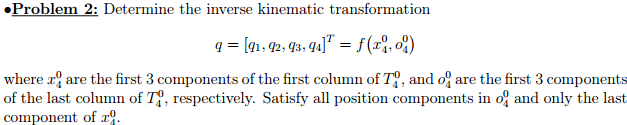

syms x_c y_c z_c
theta_1 = atan2(x_c, y_c)

$$theta\_1 = \text{atan2}\left(x_{c},y_{c}\right)$$


r = sqrt(x_c^2 + y_c^2)

$$r = \sqrt{{x_{c}}^{2}+{y_{c}}^{2}}$$

s = z_c - d_1

$$s = z_{c}-\frac{1}{20}$$

c_3 = (r^2 + s^2 - a_2^2 - a_3^2)/(2*a_2*a_3)

$$c\_3 = \frac{144115188075855872\,{\left(z_{c}-\frac{1}{20}\right)}^{2}}{2492904523336155}+\frac{144115188075855872\,{x_{c}}^{2}}{2492904523336155}+\frac{144115188075855872\,{y_{c}}^{2}}{2492904523336155}-1$$

format shortG
theta_3_1 = vpa(atan2(c_3, 1-c_3^2), 2)

$$theta\_3\_1 = \text{angle}\left(58.0\,{\left(z_{c}-0.05\right)}^{2}\,\mathrm{i}-1.0\,{\left(58.0\,{\left(z_{c}-0.05\right)}^{2}+58.0\,{x_{c}}^{2}+58.0\,{y_{c}}^{2}-1.0\right)}^{2}+58.0\,{x_{c}}^{2}\,\mathrm{i}+58.0\,{y_{c}}^{2}\,\mathrm{i}+1.0-1.0\,\mathrm{i}\right)$$

theta_3_2 = vpa(atan2(c_3, -1-c_3^2), 2)

$$theta\_3\_2 = \text{angle}\left(58.0\,{\left(z_{c}-0.05\right)}^{2}\,\mathrm{i}-1.0\,{\left(58.0\,{\left(z_{c}-0.05\right)}^{2}+58.0\,{x_{c}}^{2}+58.0\,{y_{c}}^{2}-1.0\right)}^{2}+58.0\,{x_{c}}^{2}\,\mathrm{i}+58.0\,{y_{c}}^{2}\,\mathrm{i}-1.0-1.0\,\mathrm{i}\right)$$

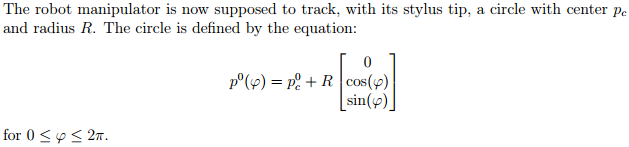

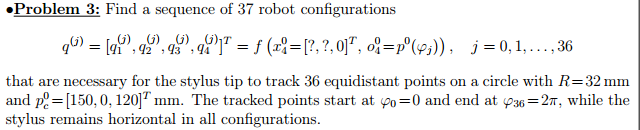

R = 0.032;
